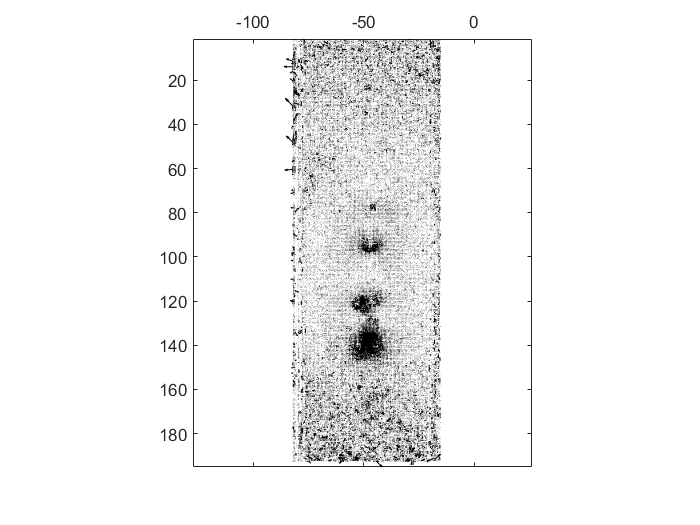

clear all;
opts = detectImportOptions('experiment_infoMatLab.csv');
ExperimentInfo = readtable('experiment_infoMatLab.csv');
ReadingPath = './data/matlabPIVinfo/';
ID = ExperimentInfo.ID;
for i = 1:1
    Name = ID{i};
    load([ReadingPath, Name, '.mat']);
    for k = 100:100
        figure(1)
        clf;
        U = Uall(:,k); V = Vall(:,k);
        
        
        %quiver(Y,X,V,U,5, 'k');
        quiver(X,Y,U,V,5, 'k');
        camroll(-90);
        axis equal;
    end
end